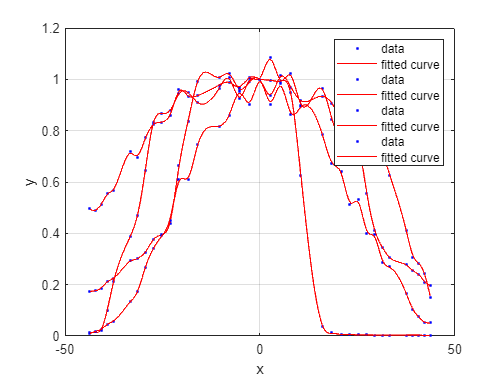

theta = rad2deg(theta1');
[AS_R_fitresult, AS_R_gof, AS_R_X, AS_R_Y] = createFit(theta, AS_R);
hold on
[AS_G_fitresult, AS_G_gof, AS_G_X, AS_G_Y] = createFit(theta, AS_G);
[AS_B_fitresult, AS_B_gof, AS_B_X, AS_B_Y] = createFit(theta, AS_B);
[AS_W_fitresult, AS_W_gof, AS_W_X, AS_W_Y] = createFit(theta, AS_W);
hold off

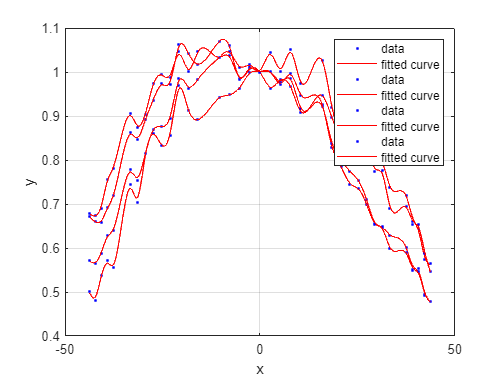

% figure("Normalise Spectral Response vs Angle","huh")

[VEML_R_fitresult, VEML_R_gof, VEML_R_X, VEML_R_Y] = createFit(theta, VEML_R);
hold on
[VEML_G_fitresult, VEML_G_gof, VEML_G_X, VEML_G_Y] = createFit(theta, VEML_G);
[VEML_B_fitresult, VEML_B_gof, VEML_B_X, VEML_B_Y] = createFit(theta, VEML_B);
[VEML_W_fitresult, VEML_W_gof, VEML_W_X, VEML_W_Y] = createFit(theta, VEML_W);
hold off

function [fitresult, gof, xData, yData] = createFit(theta1, ANGLE)
    %CREATEFIT(THETA1,AS_R)
    %  Create a fit.
    %
    %  Data for 'untitled fit 1' fit:
    %      X Input: theta1
    %      Y Output: AS_R
    %  Output:
    %      fitresult : a fit object representing the fit.
    %      gof : structure with goodness-of fit info.
    %
    %  See also FIT, CFIT, SFIT.
    
    %  Auto-generated by MATLAB on 22-Oct-2023 16:27:10
    
    
    %% Fit: 'untitled fit 1'.
    [xData, yData] = prepareCurveData( theta1, ANGLE );
    
    % Set up fittype and options.
    ft = fittype( 'smoothingspline' );
    opts = fitoptions( 'Method', 'SmoothingSpline' );
    opts.SmoothingParam = 0.9;
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft, opts );
    
    % Plot fit with data.
    % figure( 'Name', 'untitled fit 1' );
    plot( fitresult, xData, yData );
    % legend('AS_R vs. theta1', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
    % Label axes
    % xlabel( 'theta1', 'Interpreter', 'none' );
    % ylabel( 'AS_R', 'Interpreter', 'none' );
    grid on
end